**Problem 0. **Download the .mat file 

file = load('Homework3.mat');

**Problem 1. **The `score1` and `score2` variables in Homework3.mat contain scores for 100 subjects on two different tests. Fit a linear model (*y* = *ax*+ *b*) to these data, attempting to predict `score2` from `score1`. Visualize the data using a scatter plot and visualize the fitted model using a line. Report the estimated parameters in the figure title.

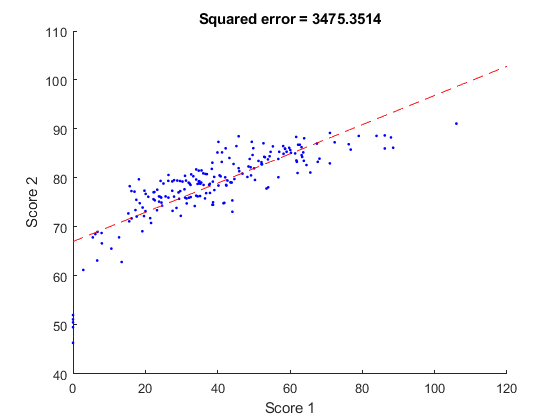

score1 = file.score1;
score2 = file.score2;

% Regressor matrix for ax+b
X = [score1(:) ones(length(score1),1)];

% Calculating weights using OLS
w = inv(X'*X)*X'*score2(:);

% Calculate the weighted sum for model
modelfit = X*w;

% Calculate the error for modelfit
sqer = sum((score2(:)-modelfit).^2);

% Plot values
figure;
hold on;
scatter(score1, score2, 'b.');
ax = axis;

% Plot predictions
% First, take 100 x values in range of x-axis limits.
% The limits are set according to existing scatter values.
xx = linspace(ax(1), ax(2), 100);
% Then, calculate the model result, using regressor and weights.
yy = [xx(:) ones(length(xx),1)] * w;
% Plot the computed values
plot(xx, yy, 'r--');
xlabel('Score 1');
ylabel('Score 2');
title(sprintf('Squared error = %.4f', sqer));
hold off;

**Problem 2. **Redo problem 1, this time using a quadratic model (*y* = *ax*2 + *bx* +*c*).

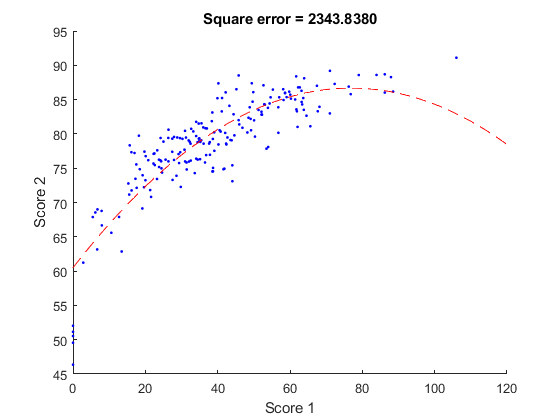

% Construct the regressor matrix
X = [score1(:).^2 score1(:) ones(length(score1),1)];
% And repeat all the actions from the previous task
w = inv(X'*X)*X'*score2(:);
modelfit = X * w;
sqer = sum((score2(:)-modelfit).^2);

figure; hold on;
scatter(score1, score2, 'b.');
ax = axis;
xx = linspace(ax(1), ax(2), 100);
yy = [xx(:).^2 xx(:) ones(length(xx),1)]*w;
plot(xx,yy,'r--');
xlabel('Score 1');
ylabel('Score 2');
title(sprintf('Square error = %.4f', sqer));
hold off;

**Problem 3. **Redo problem 1, this time using the model *y* = *axn* + *b*. Start from two different initial seeds: *a* = 1, *n*= 1, *b* = 0 and *a* = 10, *n* = 7, *b* = 100. Plot the model that achieves a lower squared error using a regular line and plot the other model using a dashed line.

% Since the given model is parametric, we'll use another approach.
% a = 1, n= 1, b = 0
par1=[1 1 0]

par1 =      1     1     0


% a = 10, n = 7, b = 100
par2=[10 7 100]

par2 =     10     7   100



% Define the optimization parameters:
options = optimset('Display','iter','FunValCheck','on', ...
'MaxFunEvals',Inf,'MaxIter',Inf, ...
'TolFun',1e-6,'TolX',1e-6);

% Define the bounds:
ub = [Inf Inf Inf];
lb = [-Inf -Inf -Inf];

% Define the model function:
modelfunc = @(pp, xx) pp(1)*xx.^pp(2) + pp(3);

% Fit the model
[params1, resnorm1] = lsqcurvefit(modelfunc, par1, score1, score2, lb, ub, options);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          4          350877                      9.33e+05
     1          8          142784             10       1.96e+05      
     2         12           50428             20       7.63e+04      
     3         16         3081.33        24.6048       7.46e+03      
     4         20         3081.33        5.49811       7.46e+03      
     5         24          2952.7        1.37453       2.94e+04      
     6         28         2328.91       0.343632            321      
     7         32         2138.52       0.687264       4.79e+03      
     8         36         1953.21        1.37453       1.55e+04      
     9         40         1698.71        1.37453       1.12e+04      
    10         44         1698.71        3.19799       1.12e+04      
    11         48          1576.4       0.687264       2.19e+03      
    12         52         1518.7

[params2, resnorm2] = lsqcurvefit(modelfunc, par2, score1, score2, lb, ub, options);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          4     3.10275e+30                      1.43e+31
     1          8      2.1331e+16             10       2.57e+22      
     2         12         98712.3    8.29149e-07       3.74e+11      

Local minimum possible.

lsqcurvefit stopped because the size of the current step is less than
the selected value of the step size tolerance.

<

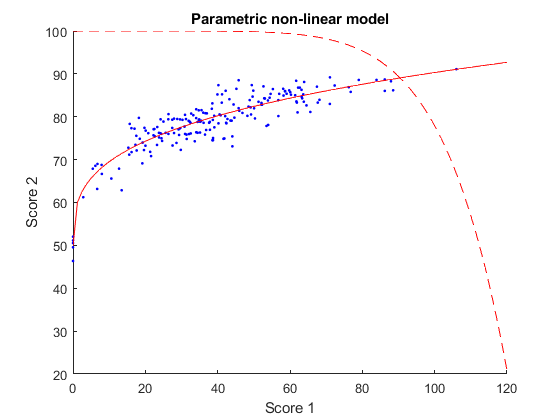


figure; hold on;
scatter(score1, score2, 'b.');
ax = axis;
xx = linspace(ax(1), ax(2), 100);
line1 = plot(xx, modelfunc(params1, xx), 'r-');
line2 = plot(xx, modelfunc(params2, xx), 'r-');
xlabel('Score 1');
ylabel('Score 2');
title('Parametric non-linear model')
% The most precise graph will be solid
if(resnorm1>resnorm2)
    set(line1, 'LineStyle', '--');
else
    set(line2, 'LineStyle', '--');
end

**Problem 4. **Perform gradient descent to fit the model described in Problem 1  (*y* = *ax*+ *b*) (see the lecture notes for Stats Lecture 4). (Hint: The amount by which to update the weights is a tricky issue. After computing the gradient vector, normalize it to have a length of one. Then update the weights by a small fraction of this vector.) Report to the command window the parameter estimates obtained by your gradient descent routine. Confirm that they are more or less identical to the parameter estimates you obtained in Problem 1.

% First of all, initialize the parameters (weight and stuff):
w = rand(2, 1).*10;

% Regressor
X = [score1(:) ones(length(score1),1)];

% Then, define the gradient descent step
step = 0.01;

% Then, define the variables for gradient descent
olderror = Inf;
curweight = w;

% Start descending
while 1
    curerror = sum((score2-X*curweight).^2);
    
    % Stop if current error exceeds the old
    if (curerror >= olderror)
        break;
    end
    
    oldweight = curweight;
    olderror = curerror;
    
    % Compute gradient vector and 
    grad = -2*X'*(score2-X*curweight);
    grad = grad/sqrt(sum(grad.^2));
    
    curweight = curweight - step*grad;
    
end

w = oldweight;
sprintf('Weights obtained by gradient descent method: \n%.2f; %.2f', w)

ans =     'Weights obtained by gradient descent method: 
     0.30; 67.03'


sprintf('Weights obtained by OLC: \n%.2f; %.2f', inv(X'*X)*X'*score2)

ans =     'Weights obtained by OLC: 
     0.30; 67.03'
